This is all for a searchlight radius of 3!

DataTable01 = getDataTable01();


**MDL01.00: **

**Hippocampus axis test (preregister version, combined hemispheres, no mixed model) **

[~,p,ci, stats] = ttest(DataTable01.zCorr_comb)

p = 0.4231

ci =    -0.0918
    0.0396


stats = struct with fields:
    tstat: -0.8122
       df: 30
       sd: 0.1791


fprintf('t(%i) = %.3g, p = %.3g, 95%% CI [%.3g, %.3g]',...
    stats.df,stats.tstat, p,ci(1), ci(1));

t(30) = -0.812, p = 0.423, 95% CI [-0.0918, -0.0918]

There appears to be no significant effect.

Testing with a one tailed t-test is probably more appropriate given we specified the direction:

[~,p,ci, stats] = ttest(DataTable01.zCorr_comb,0,"Tail","left");
fprintf('t(%i) = %.3g, p = %.3g, 95%% CI [%.3g, %.3g]',...
    stats.df,stats.tstat, p,ci(1), ci(1));

t(30) = -0.812, p = 0.212, 95% CI [-Inf, -Inf]

There was no significant effect here, so we do not have evidence to support the strongest version of the axis hypothesis.

 Next we check if the axis effect is present in dependance with behaviour. Perhaps this would allow us to delineate between those for whom q value estimates are noise and who's q values might genuinley be accurate? (I don't think this is good logic so not sure how to frame it, maybe what we actually need as a predictor is how closely their pattern sim matches the structure as a predictor of the axis-effect? 

does this mean leakage across the model? it would mean entering a predictor which is losely related to the outcome variable)

### Mdl01.01

formula = 'zCorr_comb ~ 1 + mcPnonc';
mdl01_01 = fitlm(DataTable01,formula)

mdl01_01 = Linear regression model:
    zCorr_comb ~ 1 + mcPnonc

Estimated Coefficients:
                    Estimate        SE        tStat      pValue 
                   __________    ________    ________    _______

    (Intercept)     -0.026132     0.03255    -0.80284     0.4286
    mcPnonc        -0.0099794    0.017834    -0.55959    0.58006


Number of observations: 31, Error degrees of freedom: 29
Root Mean Squared Error: 0.181
R-squared: 0.0107,  Adjusted R-Squared: -0.0234
F-statistic vs. constant model: 0.313, p-value = 0.58

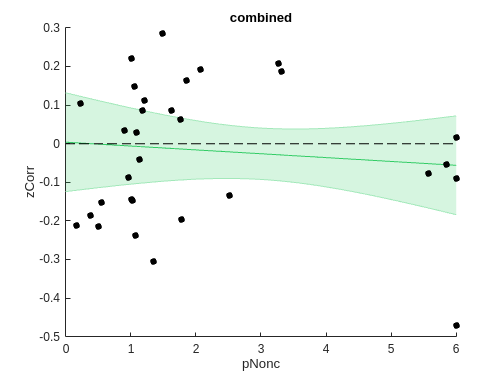

x = linspace(0,6,144);
[~,y,low,upp] = getXEUL(mdl01_01,...
    1,x-mean(x));
figure;
hold on
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.2,0.8,0.4]})
scatter(DataTable01.pNonc,DataTable01.zCorr_comb,30,'k','filled')
ylabel('zCorr');
xlabel('pNonc');
line([0,6],[0,0],'Color','k','LineStyle','--');
title('combined');
hold off;

Niether the intercept, ie. whether zCorr (across both left and right hemisphere) was diferent from zero, nor the generalisation predictor were signficant in this model, 

### Mdl01.02


% Number of subjects
n = height(DataTable01);

% Repeat subjects twice, and mean-centred pNonc
Subject = [DataTable01.subjectId; DataTable01.subjectId];
mcPnonc = [DataTable01.mcPnonc; DataTable01.mcPnonc];

% Stack zCorr values (left first, then right)
zCorr = [DataTable01.zCorr_l; DataTable01.zCorr_r];

% Binary hemisphere indicators, left =-1
hemisphere  = [ones(n,1).*-1; ones(n,1)];

% Create new table
T_long = table(Subject,mcPnonc,zCorr, hemisphere);

formula = 'zCorr ~ 1 + mcPnonc + hemisphere + (1 | Subject)';
mdl01_02 = fitlme(T_long,formula)

mdl01_02 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              61
    Fixed effects coefficients           3
    Random effects coefficients         31
    Covariance parameters                2

Formula:
    zCorr ~ 1 + mcPnonc + hemisphere + (1 | Subject)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -22.739    -12.184    16.369           -32.739 

Fixed effects coefficients (95% CIs):
    Name                   Estimate       SE          tStat       DF    pValue     Lower        Upper   
    {'(Intercept)'}           -0.02894    0.026908     -1.0755    58     0.2866    -0.082803    0.024923
    {'mcPnonc'    }        -0.00056464    0.015089    -0.03742    58    0.97028    -0.030769    0.029639
    {'hemisphere' }          -0.020169    0.020871    -0.96637    58    0.33787    -0.061946    0.021608

Random effects co

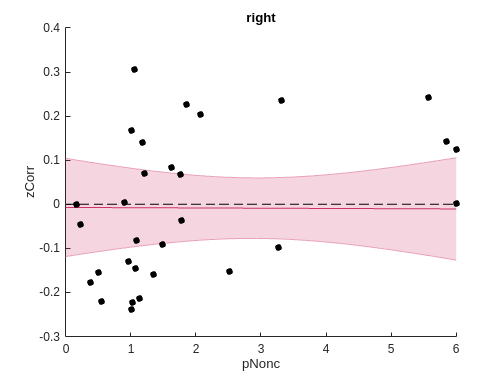


x = linspace(0,6,144);
[~,y,low,upp] = getXEUL(mdl01_02,...
    1,x-mean(x),1);
figure;
hold on
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.8,0.2,0.4]})
scatter(DataTable01.pNonc,DataTable01.zCorr_r,30,'k','filled')
ylabel('zCorr');
xlabel('pNonc');
line([0,6],[0,0],'Color','k','LineStyle','--');
title('right');
hold off;

There appears to be no relationship between yCoord and q-term even when looking at the hippocampus in specifically in one hemisphere 

Next we can ask, more broadly are we seeing a difference in q-term (i.e. distance sensitivity) that differs between anterior and posterior hippocampus. 

Given that we only observed an asscoiation between generalisation and template correlation in the right Posterior hipp (seemingly both hemis in the anterior) its reasonable to look at the right hemisphere specifically for this resolution axis.  However, we don't have enough people who have valid qs in both the  Posterior and Anterior right hippocampus in order to test the difference in log(q) here (see df=1 below). This is for a single q term asscociated with the similarity pattern estimated across the whole roi - hence you only get one shot at a estimating valid q per person per roi. However, when estimating q based on similarity patterns estimated via a searchlight, we get many qs for each person, spread across the brain, though not always located within the hippocampus.

What we can do is test whehter the log of mean qs found within the roi for each person are different in the posterior vs anterior hippocampus. However, this analysis also demonstrates no difference in the log(q) values between the anterior and posterior hippocampus.

Ignore everything below this

I also had a look at whether an interaction would come out between the quality of the patternSim (i.e. zTemplate) and the difference in resolution (i.e. log(q)) between anterior and posterior hippocampus (e.g. when zTemplate is greater, then logQ is greater for the anterior hipp than the posterior hipp) but this analysis did not yield any significant interactions.

### Mdl01.03

[ts,dt1,dt2] = getAP_qVals();

getAP_qVals is not found in the current folder or on the MATLAB path, but exists in:
    /home/sophie/Documents

Change the MATLAB current folder or add its folder to the MATLAB path.

%Method 1: honing in on where we saw behaviourally-relevant pattern Sim (in the hipp) 
fprintf('t(%i) = %.3g, p = %.3g, 95%% CI [%.3g, %.3g]',...
    ts.m1.r{3}.df,ts.m1.r{3}.tstat, ts.m1.r{1},ts.m1.r{2}(1,1),ts.m1.r{2}(2,1));

%Method 2: Looking at meaned q's found via searchlight-obtained patterns 
fprintf('\n t(%i) = %.3g, p = %.3g, 95%% CI [%.3g, %.3g]',...
    ts.m2{3}.df,ts.m2{3}.tstat, ts.m2{1},ts.m2{2}(1,1),ts.m2{2}(2,1));


% quality of structure as a predictor?

lQ = [dt2.lMuQ_A_l;dt2.lMuQ_A_r; dt2.lMuQ_P_l; dt2.lMuQ_P_r];
sagittal = [ones((height(dt2)*2),1)*-1; ones((height(dt2)*2),1)]; %coding ant as -1 
zTemplate = [dt1.zTempA_l;dt1.zTempA_r;dt1.zTempP_l;dt1.zTempP_r];
hemisphere = [ones(height(dt2),1)*-1;ones(height(dt2),1);...%coding left as -1
    ones(height(dt2),1)*-1; ones(height(dt2),1)];
subjectId = repmat(dt2.Subject,[4,1]);
dt3 = table(lQ,sagittal,zTemplate, hemisphere, subjectId);
%formula = 'lQ ~  1 + sagittal + zTemplate';
formula = 'lQ ~  1 + sagittal*hemisphere*zTemplate + (1| subjectId)';
%mdl01_03 = fitlm(dt3,formula)
mdl01_03 = fitlme(dt3,formula)
%plotSlice(mdl01_03);

### Final graph

plot([1,2],[dt2.lMuQ_A,dt2.lMuQ_P], '-','Color','k');
xlim([0,3])
ylim([-1,1])
hold on
plot(ones(size(dt2.lMuQ_A)), dt2.lMuQ_A, 'ko', ...
    'MarkerFaceColor','k', 'MarkerSize',6)

plot(2*ones(size(dt2.lMuQ_P)), dt2.lMuQ_P, 'ko', ...
    'MarkerFaceColor','k', 'MarkerSize',6)
xticks([1 2])
xticklabels({'Anterior','Posterior'})
ylabel('log of mean Q term')
hold off